# Australian Temperatures

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

data = readtable("./data/marchTemps.csv");
lonvec = 110:155;
latvec = -45:-10;
[longrid, latgrid] = meshgrid(lonvec, latvec);
Tgrid = griddata(data.longitude, data.latitude, data.temperature, longrid, latgrid);

## Task 1

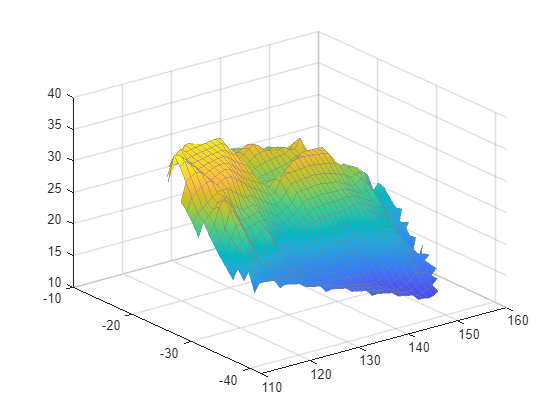

s = surf(longrid, latgrid, Tgrid);
s.EdgeColor = 0.5*[1 1 1];
s.EdgeAlpha = 0.5;
s.FaceColor = "interp";